

XLabelopts.FontSize = 18;
XLabelopts.Interpreter = "latex";
YLabelopts.FontSize = 18;
YLabelopts.Interpreter = "latex";
axopts.FontSize = 14;
axopts.Box = "on";
axopts.FontName = "Times";  % "LiberationSerif"
lgdopts.Location = "best";
lgdopts.FontSize = 14;
lgdopts.FontName = "Times";
lgdopts.Interpreter = "latex";
lgdopts.box = "off";

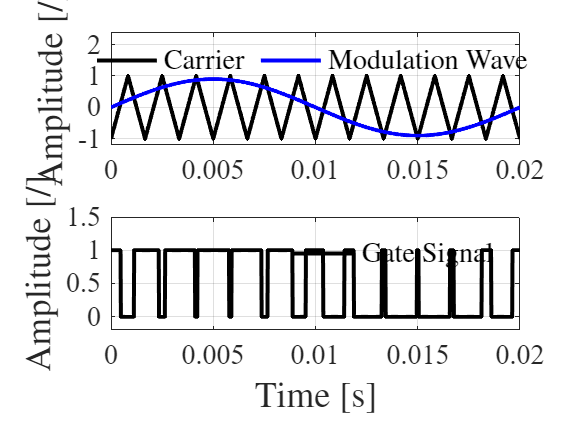

% 参数设置
fs = 50*12; % 载波频率 (Hz)
fm = 50; % 调制波频率 (Hz)
M = 10; % 载波的调制倍数
Am = .9; % 调制波幅值
Ac = 1; % 载波幅值
T = 1 / fm; % 调制波的周期
t = 0:1/(fs*100):T; % 时间向量，1.5 个周期

% 正弦调制波生成
mod_wave = Am * sin(2*pi*fm*t);

% 生成四个偏移的三角载波
triangle_wave1 = Ac * sawtooth(2*pi*fs*t, 0.5); % 第一个载波
% triangle_wave2 = Ac * sawtooth(2*pi*fs*t - pi/2, 0.5); % 第二个载波，偏移 45°
% triangle_wave3 = Ac * sawtooth(2*pi*fs*t - pi, 0.5); % 第三个载波，偏移 90°
% triangle_wave4 = Ac * sawtooth(2*pi*fs*t - 3*pi/2, 0.5); % 第四个载波，偏移 135°

% 生成 Gate Signal
gate_signal1 = mod_wave > triangle_wave1; % Gate 信号 1
% gate_signal2 = mod_wave > triangle_wave2; % Gate 信号 2
% gate_signal3 = mod_wave > triangle_wave3; % Gate 信号 3
% gate_signal4 = mod_wave > triangle_wave4; % Gate 信号 4

% 绘图
figure;
tiledlayout(2, 1);

% 绘制调制波和载波
ax1 = nexttile;
grid on
hold on;


plot(t, triangle_wave1, Color='k', LineWidth=2);
% plot(t, triangle_wave2, Color='g', LineWidth=1);
% plot(t, triangle_wave3, Color='b', LineWidth=1);
% plot(t, triangle_wave4, Color='m', LineWidth=1);
plot(t, mod_wave, Color='b', LineWidth=2);
% title('Modulation Wave and Carriers');
% xlabel('Time [s]');
ylabel('Amplitude [/]');
ylim([-1.2, 2.4]);
ax = gca;
set(ax, axopts);
set(ax.XLabel, XLabelopts);
set(ax.YLabel, YLabelopts);

label = ["Carrier", "Modulation Wave"];
lgd = legend(label, NumColumns=2);
set(lgd, lgdopts)

ax2 = nexttile;
grid on
hold on
plot(t, gate_signal1, Color='k', LineWidth=2);
% plot(t, gate_signal2, Color='g', LineWidth=1.5);
% plot(t, gate_signal3, Color='b', LineWidth=1.5);
% plot(t, gate_signal4, Color='m', LineWidth=1.5);

xlabel('Time [s]');
ylabel('Amplitude [/]');
ylim([-.2, 1.5]);
ax = gca;
set(ax, axopts);
set(ax.XLabel, XLabelopts);
set(ax.YLabel, YLabelopts);
label = ["Gate Signal"];
lgd = legend(label, NumColumns=4);
set(lgd, lgdopts)
lgd.Location = "northeast";

linkaxes([ax1, ax2], "x")

exportgraphics(gcf, "./fig/pwm.eps");

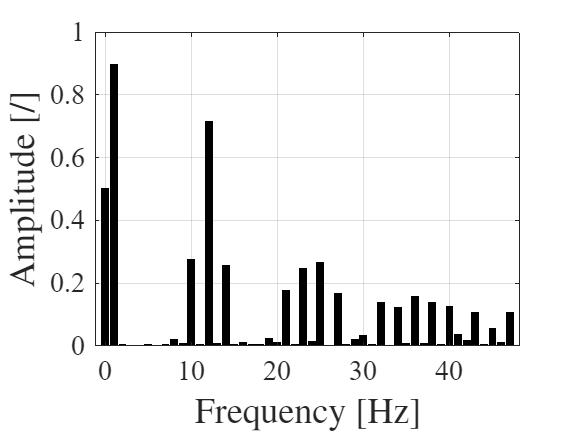

Y = fft(gate_signal1);
f = fs / length(t) * 0: floor(length(t)/2);
P2 = abs(Y/length(t));
P1 = P2(1: ceil(length(t)/2));
P1(2:end-1) = 4*P1(2:end-1);

figure;
bar(f(1:12*4), P1(1:12*4), 'k')
grid on

xlabel('Frequency [Hz]');
ylabel('Amplitude [/]');
ax = gca;
set(ax, axopts);
set(ax.XLabel, XLabelopts);
set(ax.YLabel, YLabelopts);

exportgraphics(gcf, "./fig/pwm_spectrum.eps");

% figure;
% 
% t = Vo.time;
% 
% grid on
% hold on
% plot(t, Vo.signals.values, LineWidth=1)
% % plot(t(120000:end), .7*ones(1, length(t(120000:end))), LineStyle="--", Color="k", LineWidth=2)
% % plot(t(120000:end), -.7*ones(1, length(t(120000:end))), LineStyle="--", Color="k", LineWidth=2)
% xline(1, LineStyle= "--", LineWidth=2, Color="k")
% xlim([0 1.5])
% % ylim([-1.3 1.3])
% xlabel("Time [s]")
% ylabel("$v_o$ [p.u.]")
% % xticks([.9 1 1.4])
% 
% ax = gca;
% set(ax, axopts);
% set(ax.XLabel, XLabelopts);
% set(ax.YLabel, YLabelopts);
% % annotation("textarrow", [.75, .8], [.8, .75], String="$\approx 0.65$ p.u.", Interpreter="latex", FontSize=14)
% exportgraphics(gcf, "./fig/Vo0.eps");

% figure;
% 
% grid on 
% hold on
% 
% plot(t, Vac.signals.values/Vnom_AC*sqrt(3/2), LineWidth=.5)
% plot(t(110000:end), .3*ones(1, length(t(110000:end))), LineStyle="--", Color="k", LineWidth=2)
% plot(t(110000:end), -.3*ones(1, length(t(110000:end))), LineStyle="--", Color="k", LineWidth=2)
% xline(1, LineStyle= "--", LineWidth=2, Color="k")
% % xlim([.9 1.4])
% ylim([-1.2 1.2])
% xlabel("Time [s]")
% ylabel("$v_{ac}$ [p.u.]")
% % xticks([.9 1 1.4])
% 
% ax = gca;
% set(ax, axopts);
% set(ax.XLabel, XLabelopts);
% set(ax.YLabel, YLabelopts);
% annotation("textarrow", [.75, .8], [.7, .64], String="$= 0.3$ p.u.", Interpreter="latex", FontSize=14)
% exportgraphics(gcf, "./fig/Vac0.eps");

% figure;
% 
% grid on 
% hold on
% 
% plot(t, Io.signals.values, LineWidth=.5)
% plot(t(100000:end), .32*ones(1, length(t(100000:end))), LineStyle="--", Color="k", LineWidth=2)
% plot(t(100000:end), -.32*ones(1, length(t(100000:end))), LineStyle="--", Color="k", LineWidth=2)
% xline(1, LineStyle= "--", LineWidth=2, Color="k")
% xlim([0 1.5])
% ylim([-.5 .5])
% xlabel("Time [s]")
% ylabel("$I_o$ [p.u.]")
% % xticks([.9 1 1.4])
% 
% ax = gca;
% set(ax, axopts);
% set(ax.XLabel, XLabelopts);
% set(ax.YLabel, YLabelopts);
% annotation("textarrow", [.8, .84], [.85, .79], String="$\approx 0.3$ p.u.", Interpreter="latex", FontSize=14)
% exportgraphics(gcf, "./fig/Io0.eps");

% figure;
% 
% grid on 
% hold on
% 
% plot(t, freq.signals.values, LineWidth=2, Color="k")
% xline(1, LineStyle= "--", LineWidth=2, Color="k")
% xlim([0 1.5])
% ylim([49.8 50.2])
% xlabel("Time [s]")
% ylabel("Frequency $f$ [Hz]")
% % xticks([0 1 3])
% 
% ax = gca;
% set(ax, axopts);
% set(ax.XLabel, XLabelopts);
% set(ax.YLabel, YLabelopts);
% % annotation("textarrow", [.75, .8], [.72, .65], String="$\approx 0.7$ p.u.", Interpreter="latex", FontSize=14)
% exportgraphics(gcf, "./fig/f0.eps");